## Transformada de Fourier

En este cuaderno exploraremos la Transformada de Fourier de algunas señales y una aplicación de ejemplo.

La transformada de Fourier de una señal aperiódica continua está definida por:


$$X(j\omega) = \mathcal{F}\{x(t)\} = \int_{-\infty}^{+\infty}x(t)e^{-j\omega t}dt$$


La Transformada inversa de Fourier de una señal aperiódica está definida por:


$$x(t) = \mathcal{F}^{-1}\{X(j\omega)\} = \frac{1}{2\pi}\int_{-\infty}^{+\infty}X(j\omega)e^{j\omega t}d\omega$$


### Ejemplo 1: 

### Transformada de Fourier de Señal Rectangular:

Determinar y Graficar la Transformada de Fourier de la señal:


$$rect(t) = \begin{cases}
1 & -\pi/2 \leq t \leq \pi/2 \\
0 & |t|>\pi/2
\end{cases}$$


Podemos usar Matlab para calcular simbólicamente la Transformada de Fourier

syms t
f = rectangularPulse(-pi/2, pi/2, t)

$$f = \mathrm{rectangularPulse}\left(-\frac{\pi }{2},\frac{\pi }{2},t\right)$$

X = fourier(f)

$$X = \frac{\sin\left(\frac{\pi \,w}{2}\right)+\cos\left(\frac{\pi \,w}{2}\right)\,\mathrm{i}}{w}-\frac{-\sin\left(\frac{\pi \,w}{2}\right)+\cos\left(\frac{\pi \,w}{2}\right)\,\mathrm{i}}{w}$$

simplify(X)

$$ans = \frac{2\,\sin\left(\frac{\pi \,w}{2}\right)}{w}$$

Se obtiene que  $\mathcal{F}\{rect(t)\} = \frac{2sin(\pi\omega/2)}{\omega}$

Para graficar estos resultados procedemos como sigue

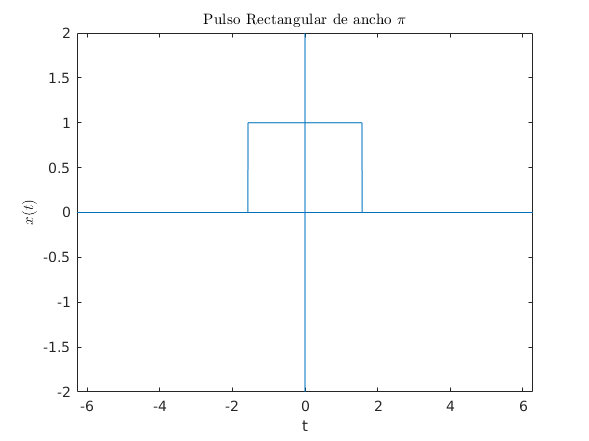

clc, clear;
T = linspace(-pi,pi, 1000);
% T = -pi:.01:pi;
x = rectpuls(T, pi);
figure(1)
plot(T, x)
xlim([-2*pi 2*pi])
ylim([-2 2])
xL = xlim;
yL = ylim;
line([0 0], yL);  %x-axis
line(xL, [0 0]);  %y-axis
xlabel("t")
ylabel("$$x(t)$$", "Interpreter","latex")
title("Pulso Rectangular de ancho $$\pi$$", "Interpreter","latex")

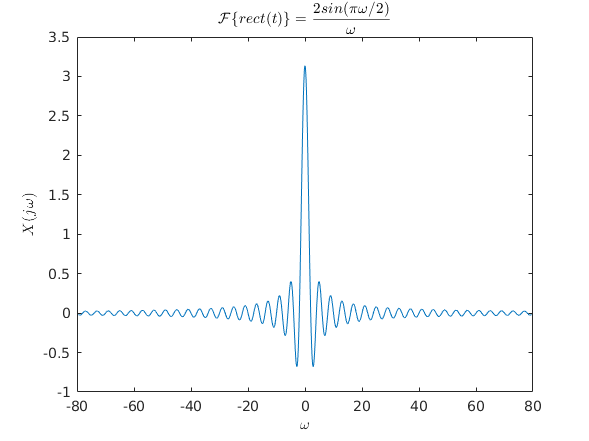

Ts = mean(diff(T));                                     % Sampling Interval
Fs = 1/Ts;                                              % Sampling Frequency
Fn = Fs/2;                                              % Nyuquist Frequency
L = length(x);
Fv = linspace(-Fn, Fn, L);  
X_jw = 2*sin(Fv*pi/2)./Fv;
figure()
plot(Fv, X_jw)
xlabel('$$\omega$$', 'Interpreter',"latex")
ylabel("$$X(j\omega)$$","Interpreter","latex")
title('$$\mathcal{F}\{rect(t)\} = \frac{2sin(\pi\omega/2)}{\omega}$$', "Interpreter","latex")

Para graficar la transformada de Fourier de la señal pulso rectangular usando la **transformada rápida de Fourier (FFT) **es necesario realizar un grafico de Amplitud y Fase.

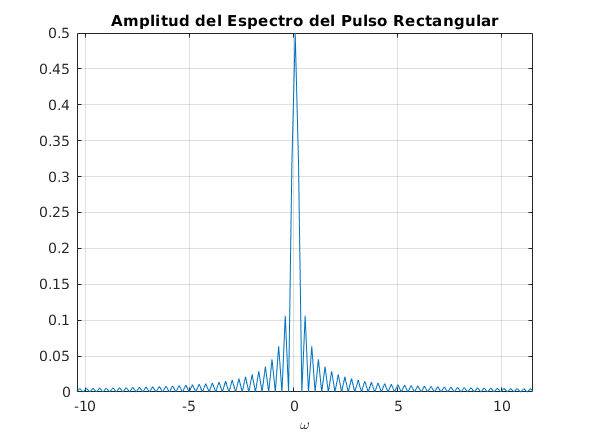

ftx = fft(x)/L;                                         % Fourier Transform
ftxs = fftshift(ftx);                                   % Shift To Centre
Fv = linspace(-Fn, Fn, L);                              % Frequency Vector
figure(2)
plot(Fv, abs(ftxs))                                     % Plot Amplitude
xlim([-10.4 11.5])
ylim([0.00 0.50])
title("Amplitud del Espectro del Pulso Rectangular")
xlabel("$$\omega$$", "Interpreter","latex")
grid

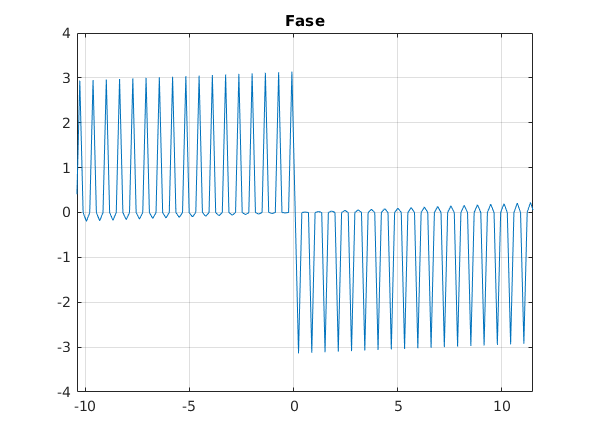

figure(3)
plot(Fv, angle(ftxs))                                   % Plot Phase
title("Fase")
xlim([-10.4 11.5])
grid

### Ejemplo 2: Transformada Inversa de Fourier de Impulso desplazado

Considere $X(j\omega) = \delta(\omega-\omega_0)$, obtener la transformada inversa de fourier

clc, clear;
syms t w0 w a 
X = dirac(w-w0)

$$X = \delta (w-w_{0})$$

x = ifourier(X, t)

$$x = \frac{{\mathrm{e}}^{t\,w_{0}\,\mathrm{i}}}{2\,\pi }$$

Entonces, $\mathcal{F}\{e^{j\omega_0t}\} = 2\pi\delta(\omega-\omega_0)$

### Ejemplo 3: Transformada de Fourier de señal sinusoidal

clc, clear;
syms t w0;
x=sin(w0*t);
X=fourier(x, w0)

$$X = -\pi \,\left(\delta (t-w_{0})-\delta (t+w_{0})\right)\,\mathrm{i}$$

De igual manera utilicemos la FFT que usa la **Transformada Discreta de Fourier**, para analizar el espectro de la señal sinusoidal

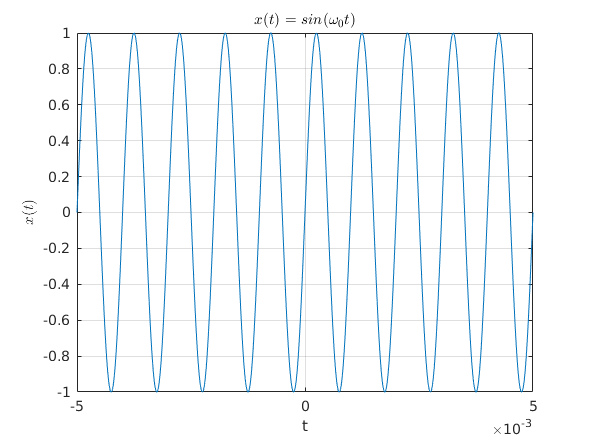

clc, clear;
f = 1000;
T = 1/f;
t_=-5*T:T/1000:5*T;
x=sin(2*pi*f*t_);
figure(1)
plot(t_,x)
xlabel("t")
ylabel("$$x(t)$$","Interpreter","latex")
title("$$x(t) = sin(\omega_0t)$$","Interpreter","latex")
grid

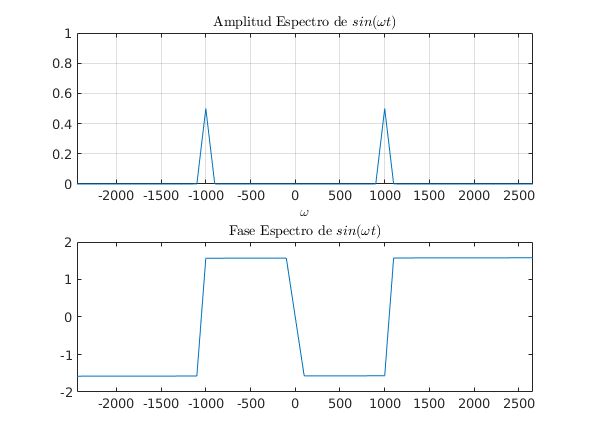

Ts = mean(diff(t_));                                     % Sampling Interval
Fs = 1/Ts;                                              % Sampling Frequency
Fn = Fs/2;                                              % Nyuquist Frequency
L = length(x);
ftx = fft(x)/L;                                         % Fourier Transform
ftxs = fftshift(ftx);                                   % Shift To Centre
Fv = linspace(-Fn, Fn, L);                              % Frequency Vector
figure(2)
subplot(2,1,1)
plot(Fv, abs(ftxs))                                    % Plot Amplitude
xlim([-2440 2658])
ylim([0.00 1.00])
xlabel("$$\omega$$","Interpreter","latex")
title("Amplitud Espectro de $$ sin(\omega t) $$","Interpreter","latex")
grid
subplot(2,1,2)
plot(Fv, angle(ftxs))                                   % Plot Phase
title("Fase Espectro de $$sin(\omega t)$$","Interpreter","latex")
xlim([-2440 2658])

### Aplicación: Utilización de FFT y su inversa para retirar la componente de ruido de una señal

En este ejemplo se generan un par de señales sinusoidales para emular una señal acústica y una señal de ruido. Mediante la Transformada Discreta de Fourier, realizando un análisis del contenido frecuencial de la señal compuesta, se tratará de obtener mediante la Transformada inversa la señal original.

Generaremos 2 señales. Una señal de 440 Hz (señal) y una a 4000 Hz (ruido). Esto es:


$$x_1 = sin(2\pi f_1t); f_1=440$$



$$x_2 = sin(2\pi f_2t); f_2=4000$$


clc, clear;
SAMPLE_RATE = 44100; % sampling
DURACION = 5; % Duracion en segundos
[t1, senal] = generar_onda_seno(440, SAMPLE_RATE, DURACION);
[t2, ruido] = generar_onda_seno(4000, SAMPLE_RATE, DURACION);
ruido = ruido*0.3;
senal_mixta = senal+ruido;



Normalizamos la onda mixta generada:

senal_mixta_norm = int16((senal_mixta/max(senal_mixta)*32767));


Realizamos un Plot de la señal:

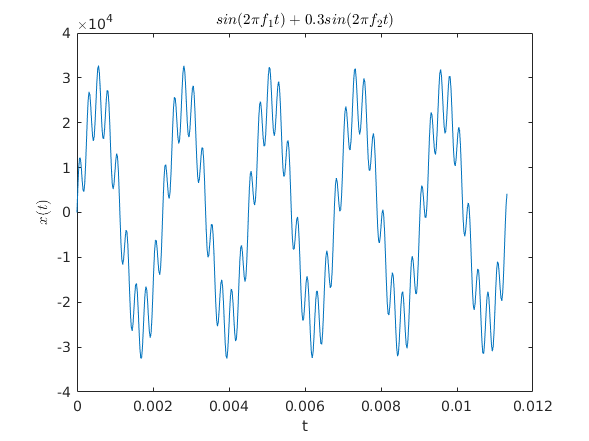

figure()
plot(t1(1:500),senal_mixta_norm(1:500))
xlabel("t")
ylabel("$$x(t)$$","Interpreter","latex")
title("$$sin(2\pi f_1t)+0.3sin(2\pi f_2t)$$", "Interpreter","latex")

Guardamos el archivo de audio:

archivo1 = fullfile(pwd, "Documents/MATLAB/Fourier/sonido_con_ruido.wav");
audiowrite(archivo1, senal_mixta_norm,SAMPLE_RATE);


Podemos reproducir el archivo para escuchar su sonido:

[sonido1,Fs] = audioread(archivo1);
% sound(sonido, Fs);

Para propósitos de comparación se guarda el archivo de sonido de la señal sin ruido:

archivo2 = fullfile(pwd, "Documents/MATLAB/Fourier/sonido_440.wav");
audiowrite(archivo2, senal,SAMPLE_RATE);
[sonido2,Fs] = audioread(archivo2);
% sound(sonido, Fs);

#### Oteniendo la Transformada Rápida de Fourier

Instalar la función fftfreq desde el administrador de Add-Ons de Matlab

El comando fft obtiene la transformada rápida discreta de Fourier (DFT)

El comando fftfreq es una adaptación del comando scipy.fftfreq de Python y que permite calcular las frecuencias en el centro de cada **bin** en la salida de la `fft(). Esto facilita dibujar el ``espectro`

Note que para dibujar el espectro se ha utilizado la función abs() que permite obtener el módulo de un número complejo$abs(c+jb)=\sqrt{c^2+b^2}$

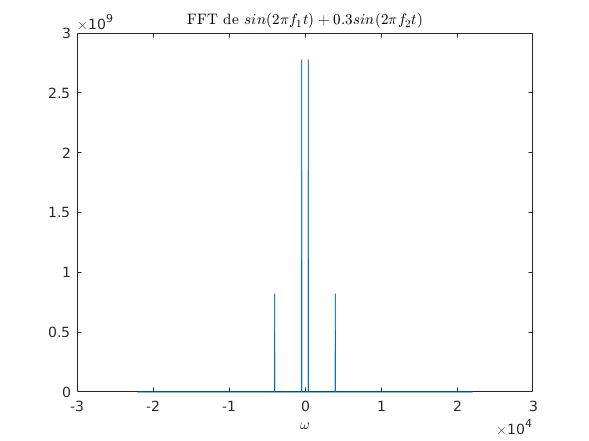

N = SAMPLE_RATE*DURACION;
yf = fft(senal_mixta_norm);
xf = fftfreq(N, 1/SAMPLE_RATE);
figure()
plot(xf,abs(yf))
xlabel("$$\omega$$","Interpreter","latex")
title("FFT de $$ sin(2 \pi f_1 t)+0.3sin(2 \pi f_2 t) $$", "Interpreter","latex")

Se observan dos picos: uno en 400 Hz y otro en 4000 Hz

Observemos algunos resultados de la fft para verificar que son números complejos:

yf(1:5)

ans = 	1.0e+02 *

   0.0000 + 0.0000i  -0.0000 + 1.1244i  -0.0000 + 0.3736i   0.0000 - 0.5286i  -0.0000 + 0.3448i


Si deseamos observar sólo la parte derecha que tienen frecuencias positivas podemos truncar los vectores xf y yf:

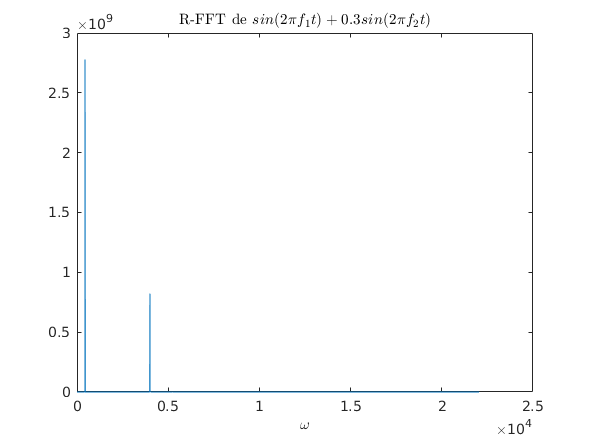

corte = length(xf)/2; % esto da 110250 ya que length(xf) = 220500
figure()
plot(xf(1:corte), abs(yf(1:corte)))
title("R-FFT de $$sin(2\pi f_1 t)+0.3sin(2\pi f_2 t)$$", "Interpreter","latex")
xlabel("$$\omega$$","Interpreter","latex")

#### Usando Transformada Inversa para reconstruir la señal original:

Para esto observamos que el contenido significativo de frecuencia sucede en 400 Hz. Por tanto el contenido con frecuencias de 4000 o más debe ser eliminado

Para encontrar el índice en el que se dan las frecuencias de 4000 hacemos:

indice_4000 = find(xf==4000); % da 20000
indice_4000neg = find(xf==-4000); % da 200501
indice_400neg = find(xf==-400); % da 218501

Enceramos el contenido de frecuencia alrededor del índice que corresponde a 4000 Hz

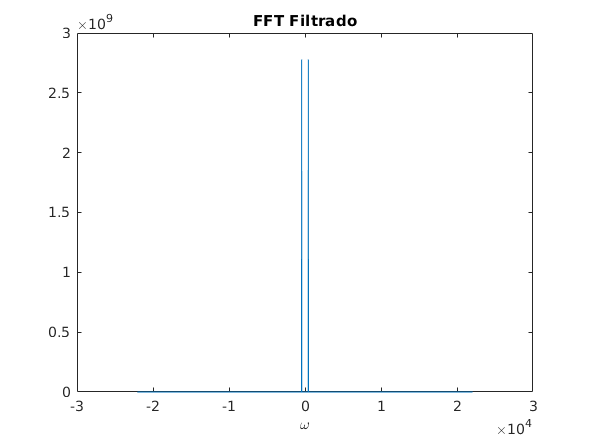

yf2 = yf;
yf2(indice_4000-250:indice_4000+250) = 0;
yf2(indice_4000neg-250:indice_4000neg+250) = 0;
% yf2(indice_400neg-250:indice_400neg+250) = 0;
figure();
plot(xf, abs(yf2))
title("FFT Filtrado")
xlabel("$$\omega$$","Interpreter","latex")

Usando la transformada inversa para obtener la señal original:

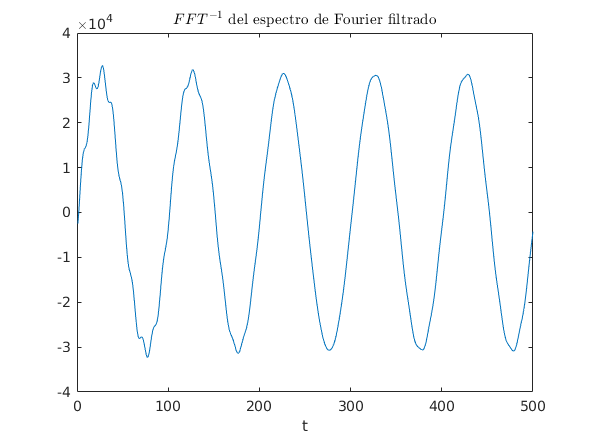

nueva_senal = ifft(yf2);
nueva_senal_norm = int16((nueva_senal/max(nueva_senal)*32767));
figure()
plot(nueva_senal_norm(1:500))
title("$$FFT^{-1}$$ del espectro de Fourier filtrado", "Interpreter","latex")
xlabel("t")

archivo3 = fullfile(pwd, "Documents/MATLAB/Fourier/sonido_ifft.wav");
audiowrite(archivo3, nueva_senal_norm,SAMPLE_RATE);
[sonido3,Fs] = audioread(archivo3);
% sound(sonido, Fs);

Finalmente, se detalla la función generar_onda_seno que utiliza como argumentos la frecuencia de la señal deseada, el número de muestras y la duración en segundos 

function [x,y] = generar_onda_seno(frec, sample, duracion)
x = linspace(0, duracion, duracion*sample);
frecuencias = x*frec;
y = sin(2*pi*frecuencias);
end


### Referencias:

- [https://realpython.com/python-scipy-fft/](https://realpython.com/python-scipy-fft/)

- Dimuthu Senanayaka (2021). Fourier Analysis of a Rectangular Pulse (https://www.mathworks.com/matlabcentral/fileexchange/25571-fourier-analysis-of-a-rectangular-pulse), MATLAB Central File Exchange. Retrieved February 21, 2021.

- [https://www.mathworks.com/matlabcentral/answers/273430-how-can-i-do-the-fft-of-a-rectpuls](https://www.mathworks.com/matlabcentral/answers/273430-how-can-i-do-the-fft-of-a-rectpuls)